%% Windfarm Short Circuit Analysis - Multi-Path Topology & Power Distribution
clear; clc;

% Define a symbolic matrix
A = sym([1 2 3 4; 5 6 7 8; 9 10 11 12; 13 14 15 16]);

% Display as a LaTeX string
latex(A)

ans = '\left(\begin{array}{cccc} 1 & 2 & 3 & 4\\ 5 & 6 & 7 & 8\\ 9 & 10 & 11 & 12\\ 13 & 14 & 15 & 16 \end{array}\right)'

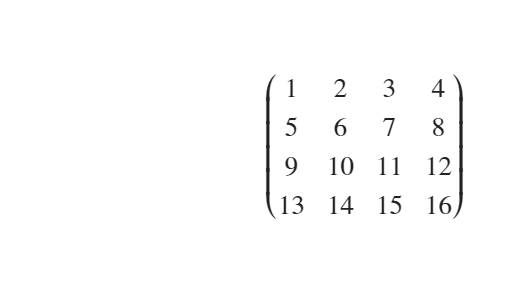


% To see it rendered visually in a figure window:
t = text(0.5, 0.5, ['$', latex(A), '$'], 'Interpreter', 'latex', 'FontSize', 20);
axis off;



% 1. Symbolen voor onbekenden (Grid & Compensatie)
syms S_sc_onshore L_shore L_substation Z_turbine S_grid ST1 ST2 ST3 ST4 ST5
syms Z1 Z2 Z3 Z4 Z5 Z6 Z7 Z8 Z9 Z10 Z11 Z12 Z13 Z14 Z15 Zgrid_0 Zgrid
syms ZL1 ZL2 ZL3 ZL4 ZL5 ZL6 ZL7 ZL8 R X
syms ZTB1 ZTB2 ZTA38a ZTA38b ZTA37 Z_380kV Z_66kV Zeq1 Zeq2 ZR1 ZR2 ZR Sbase Ubase Ubase2 

%% -------- UPDATED POWER DISTRIBUTION (match your current Simulink & team decision) ---------

Sbase =  100e6;          % Base power (keep)
Ubase3 = 380e3;          % Onshore base
Ubase =  220e3           % 

Ubase = 220000

Ubase2 = 66e3;           % Collector base
Ugrid =  380e3

Ugrid = 380000

f = 50;
omega =  2*pi*f;

U_66kv = 66e3

U_66kv = 66000

U_220kv= 220e3

U_220kv = 220000

U_380kV= 380e3

U_380kV = 380000


% New powers (your final design)
P_b_nom = 900e6;      % Cluster B
P_a_nom = 700e6;      % A3.8 (35 turbines)

X = R*20  

$$X = 20\,R$$

f = 50;                      % Frequentie [Hz]
omega = 2 * pi * f

omega = 314.1593


%%Grid parameters calculations
S_grid    = 20e9

S_grid = 2.0000e+10

X_R_ratio = 20                                                                                                                                                         

X_R_ratio = 20

Z_grid    = U_380kV^2 / S_grid

Z_grid = 7.2200


R_grid = sqrt(Z_grid^2 / (1 + X_R_ratio^2))

R_grid = 0.3605

X_grid = X_R_ratio*R_grid*j

X_grid = 0.0000 + 7.2110i


Z_grid_0 = Z_grid * 4 

Z_grid_0 = 28.8800


Z_grid_pu = (R_grid + X_grid) * (Sbase / Ubase2^2)

Z_grid_pu = 0.0083 + 0.1655i


%Grid zero sequence impedance
X0_X1_grid_ratio = 4

X0_X1_grid_ratio = 4

Z_grid = ((380e3)^2/S_grid)*(Sbase/Ubase^2)

Z_grid = 0.0149


%% 66kV / 220kV
ST_b1_66kv = 600e6

ST_b1_66kv = 600000000

ST_b2_66kv = ST_b1_66kv

ST_b2_66kv = 600000000

ST_a_66kv = 900e6

ST_a_66kv = 900000000


%% 220kV / 380kV
ST_b_220kv = 1000e6

ST_b_220kv = 1.0000e+09

ST_a_220kv = 1000e6

ST_a_220kv = 1.0000e+09



%% Turbine equivalent (current source) impedances - updated powers
%  Normaly not used ( because we consider ideal current source ? ) 

Z_sB   = U_66kv^2 / P_b_nom;      % Cluster B
Z_sA = U_66kv^2 / P_a_nom;    % A3.8
Z_sB_pu   = Z_sB   * (Sbase / Ubase2^2);
Z_sA_pu = Z_sA * (Sbase / Ubase2^2);


% Transformers according to simulink model 
% 66/220 kv 

uk_trafo = 0.14;                                % Kortsluitspanning trafo (14%) at cluster B 
ZTB1f = uk_trafo*(U_66kv^2/ST_b1_66kv)*j        % transformer at cluster B

ZTB1f = 0.0000 + 1.0164i


ZTB2f = uk_trafo* (U_66kv^2/ST_b2_66kv)*j

ZTB2f = 0.0000 + 1.0164i

ZTAf = uk_trafo* (U_66kv^2/ST_a_66kv)*j         % transformer at cluster A ( according to simulink model )

ZTAf = 0.0000 + 0.6776i



% ZERO SEQUENCE EQUIVALENTS 
ZTB1_0 = ZTB1f*3                                

ZTB1_0 = 0.0000 + 3.0492i

ZTA_0 = ZTAf*3

ZTA_0 = 0.0000 + 2.0328i


% Other transformers according to simulink model  

ZTB1_220kv = uk_trafo*(U_220kv^2/ST_b_220kv)*j  %  380/220 transformer  

ZTB1_220kv = 0.0000 + 6.7760i

% you will find somewhere ZTB1, ZTB1 is the transformer after collector busbar. 66/ 220 kV I was not very creative with the names 

ZTB2_220kv = uk_trafo* (U_220kv^2/ST_b_220kv)*j

ZTB2_220kv = 0.0000 + 6.7760i

ZTA_220kv = uk_trafo* (U_220kv^2/ST_a_220kv)*j

ZTA_220kv = 0.0000 + 6.7760i

ZTB1_220kv_0 = ZTB1_220kv*3

ZTB1_220kv_0 = 0.0000 +20.3280i

ZTB2_220kv_0 = ZTB2_220kv*3

ZTB2_220kv_0 = 0.0000 +20.3280i

ZTA_220kv_0 = ZTA_220kv*3 

ZTA_220kv_0 = 0.0000 +20.3280i





%Transformer zero sequence parameter
X0_X1_T_ratio = 3

X0_X1_T_ratio = 3


% Export Cables 
length = 60 %The export cable length is 60km

length = 60

R_km = 0.1  %Ohm/km

R_km = 0.1000

C_km = 0.171 %uF/km  %Just mock number, could be different later on

C_km = 0.1710

L_km = 0.45 %mH/km

L_km = 0.4500


Z_line = R_km*length + j*(omega*L_km*length*10^-3) 

Z_line = 6.0000 + 8.4823i


ZLe1 = Z_line / 3  % Divided by 3 because we use 3 parallel cables 

ZLe1 = 2.0000 + 2.8274i


ZLe1_0 = ZLe1

ZLe1_0 = 2.0000 + 2.8274i


ZLe1_pu = (Z_line/3) * (Sbase/Ubase^2)

ZLe1_pu = 0.0041 + 0.0058i


ZLe1_1_pu = ZLe1_pu/2    

ZLe1_1_pu = 0.0021 + 0.0029i


ZLe1_2_pu = ZLe1_pu/2

ZLe1_2_pu = 0.0021 + 0.0029i

ZLe2_pu = Z_line * (Sbase/Ubase^2)

ZLe2_pu = 0.0124 + 0.0175i

ZLe3_pu = Z_line * (Sbase/Ubase^2)

ZLe3_pu = 0.0124 + 0.0175i


xo_x1_ratio_submarine = 1 %(could be from 1 to 1.5 because submarine cables have good return path via water and cable sheath)

xo_x1_ratio_submarine = 1

Z0Le1_pu = (Z_line/3 )* (Sbase/Ubase^2)

Z0Le1_pu = 0.0041 + 0.0058i

Z0Le1_1_pu = ZLe1_pu/2

Z0Le1_1_pu = 0.0021 + 0.0029i

Z0Le1_2_pu = ZLe1_pu/2

Z0Le1_2_pu = 0.0021 + 0.0029i




%%On shore overhead transmission cables
R1_Le_ON = 0.0209;      % ohm/km
R0_Le_ON = 0.3030;      % from RT_OPAL parameters

L1_Le_ON = 0.8467e-3;   %H/km
L0_Le_ON = 3.1544e-3;   %H/km

C1_Le_ON = 0.0137e-6;   % F/km
C0_Le_ON = 0.0084e-6;   % from RT_OPAL parameters

length_ON = 150; %km

comp = 1/(C1_Le_ON*length_ON*100*pi)

comp = 1.5490e+03

(comp / 100*pi) / length_ON

ans = 0.3244


Z1_Le_ON = R1_Le_ON*length_ON + j*L1_Le_ON*100*pi

Z1_Le_ON = 3.1350 + 0.2660i

Z0_Le_ON = R0_Le_ON*length_ON + j*L0_Le_ON*100*pi

Z0_Le_ON = 45.4500 + 0.9910i


Z1_Le_ON_pu = Z1_Le_ON * (Sbase / Ubase^2)

Z1_Le_ON_pu = 0.0065 + 0.0005i

Z0_Le_ON_pu = Z0_Le_ON * (Sbase / Ubase^2)

Z0_Le_ON_pu = 0.0939 + 0.0020i


%%Feeder cable 
%Feeder line zero sequence impedance
X0_X1_L_ratio = 3

X0_X1_L_ratio = 3


%% --- SYSTEEM PARAMETERS & VERMOGENS --- w
V_66 = 66000;                % Offshore spanning [V]
V_380 = 380000;              % Onshore spanning [V]

% Vermogensverdeling per Zone [MW]
P_B1  = 450;                 %
P_B2  = 450; 
P_A38a = 225;                 % Zone 3.8 MW
P_A38b = 225; 
P_A37 = 225;                 % Zone 3.7 MW

P_A = P_A37 + P_A38a+P_A38b

P_A = 675

%%Feeder equivalent parallel impedance
ZfLB1 = 0.244686 + j*0.153423

ZfLB1 = 0.2447 + 0.1534i

ZfLB2 = 0.20829138 + j*0.13060804

ZfLB2 = 0.2083 + 0.1306i

ZfLA38a = 0.3514672 + j*0.220373

ZfLA38a = 0.3515 + 0.2204i

ZfLA38b = 0.408561332 + j*0.2561899

ZfLA38b = 0.4086 + 0.2562i

ZfLA37 = 0.43514837 + j*0.27285307

ZfLA37 = 0.4351 + 0.2729i


% per unit value 

ZfLB1_pu = ZfLB1 * (Sbase / Ubase2^2)

ZfLB1_pu = 0.0056 + 0.0035i

ZfLB2_pu = ZfLB2 * (Sbase / Ubase2^2)

ZfLB2_pu = 0.0048 + 0.0030i

ZfLA38a_pu = ZfLA38a * (Sbase / Ubase2^2)

ZfLA38a_pu = 0.0081 + 0.0051i

ZfLA38b_pu = ZfLA38b * (Sbase / Ubase2^2)

ZfLA38b_pu = 0.0094 + 0.0059i

ZfLA37_pu = ZfLA37 * (Sbase / Ubase2^2)

ZfLA37_pu = 0.0100 + 0.0063i


%%Turbine equivalent current source circuit:


%Current source parallel impedance
Z_sB1 = U_66kv^2 / (P_B1*10^6)

Z_sB1 = 9.6800

Z_sB2 = U_66kv^2 / (P_B2*10^6)

Z_sB2 = 9.6800

Z_sA38a = U_66kv^2 / (P_A38a*10^6)

Z_sA38a = 19.3600

Z_sA38b = U_66kv^2 / (P_A38b*10^6)

Z_sA38b = 19.3600

Z_sA37 = U_66kv^2 / (P_A37*10^6)

Z_sA37 = 19.3600


Z_sB1_pu = Z_sB1 * (Sbase / Ubase2^2)

Z_sB1_pu = 0.2222

Z_sB2_pu = Z_sB2 * (Sbase / Ubase2^2)

Z_sB2_pu = 0.2222

Z_sA38a_pu = Z_sA38a * (Sbase / Ubase2^2)

Z_sA38a_pu = 0.4444

Z_sA38b_pu = Z_sA38b * (Sbase / Ubase2^2)

Z_sA38b_pu = 0.4444

Z_sA37_pu = Z_sA37 * (Sbase / Ubase2^2)

Z_sA37_pu = 0.4444

Z_A = (1/Z_sA37  + 1/Z_sA38b + 1/Z_sA38a )^-1

Z_A = 6.4533


%% 3 Phase to ground fault situation ----- On feeder B1 -------------------------------------
% Impedances transformations 
Z_grid_66kV = (66/380)^2 * Z_grid

Z_grid_66kV = 4.5000e-04

Z1_Le_ON_66kv = (66/380)^2 * Z1_Le_ON

Z1_Le_ON_66kv = 0.0946 + 0.0080i

ZTB1_220kv

ZTB1_220kv = 0.0000 + 6.7760i

Zle1_66kv = (66/220)^2 * ZLe1

Zle1_66kv = 0.1800 + 0.2545i

ZTB1_exp_66kv = ZTB1_220kv * ( 66/220)^2 

ZTB1_exp_66kv = 0.0000 + 0.6098i

ZTB1f

ZTB1f = 0.0000 + 1.0164i


Isource_1 = (450e6/(66e3*sqrt(3))) 

Isource_1 = 3.9365e+03

Isource_2 = (450e6/(66e3*sqrt(3)))

Isource_2 = 3.9365e+03

Ifault1 = Isource_1;
Ifault2 = Isource_2*  (Z_grid_66kV + Z1_Le_ON_66kv + ZTB1_exp_66kv) / (Z_grid_66kV + Z1_Le_ON_66kv + Zle1_66kv + ZTB1_exp_66kv + ZTB1f );
Isource_a = (700e6/(66e3*sqrt(3)))

Isource_a = 6.1234e+03

Ifault3 = Isource_a * (Z_grid_66kV )/ (Z_grid_66kV + Z1_Le_ON_66kv + ZTB1_exp_66kv + ZTB1f + Zle1_66kv);
Ifault2 = Ifault2

Ifault2 = 1.2892e+03 - 1.0313e+01i

Ifault3 = Ifault3

Ifault3 = 0.2080 - 1.4286i

Z = ( sqrt(3) * (Z_grid_66kV + Zle1_66kv + ZTB1f+ ZTB1_exp_66kv+ Z1_Le_ON_66kv))

Z = 0.4764 + 3.2714i

abs(Z)

ans = 3.3059


Ifault4 =  66e3/(  sqrt(3)*(Z_grid_66kV + Zle1_66kv + ZTB1f+ ZTB1_exp_66kv+ Z1_Le_ON_66kv ) ) 

Ifault4 = 2.8767e+03 - 1.9756e+04i

I_total_feeder = abs(Ifault1 + Ifault2+ Ifault3 + Ifault4)

I_total_feeder = 2.1364e+04



%% 3 Phase to ground fault situation export cable
%% 3 Current Source and 1 Voltage source. 

Ugrid

Ugrid = 380000

U= 220e3

U = 220000

Z_grid_220kv = (U/Ugrid)^2* Z_grid

Z_grid_220kv = 0.0050

Z1_Le_ON_220kv = (U/Ugrid)^2 * Z1_Le_ON       

Z1_Le_ON_220kv = 1.0508 + 0.0892i

                                        %220kv 
ZTB1_220kv 

ZTB1_220kv = 0.0000 + 6.7760i

ZTB1f_220kv = ZTB1f*(220/66)^2

ZTB1f_220kv = 0.0000 +11.2933i


Isource_1 = (450e6/(66e3*sqrt(3))) %A

Isource_1 = 3.9365e+03

Isource_2 = (450e6/(66e3*sqrt(3))) %A

Isource_2 = 3.9365e+03


Ifault1 = Isource_1*(66/220) ;

Ifault2 = Isource_2*(66/220) * (Z_grid_220kv + Z1_Le_ON_220kv + ZLe1/2 + ZTB1_220kv) / (Z_grid_220kv + Z1_Le_ON_220kv + ZLe1/2 + ZTB1_220kv + ZTB1f_220kv );

Isource_a = (700e6/(66e3*sqrt(3)))

Isource_a = 6.1234e+03

Ifault3 = Isource_a * (66/220 )*(Z_grid_220kv + Z1_Le_ON_220kv )/ (Z_grid_220kv + Z1_Le_ON_220kv + ZTB1f_220kv + ZTB1_220kv + ZLe1/2);
Ifault1

Ifault1 = 1.1809e+03

Ifault2 = abs(Ifault2)

Ifault2 = 511.8835

Ifault3 = abs(Ifault3)

Ifault3 = 98.9037

Z2 =  ( sqrt(3)*(Z_grid_220kv + ZLe1/2 + ZTB1_220kv+ Z1_Le_ON_220kv))

Z2 = 3.5607 +14.3394i

abs(Z2)

ans = 14.7749


Ifault4 = 220e3 /( sqrt(3)*( Z_grid_220kv + ZLe1/2 + ZTB1_220kv+ Z1_Le_ON_220kv ) )  

Ifault4 = 3.5885e+03 - 1.4451e+04i


I_total_feedr = abs(Ifault1 + Ifault2+ Ifault3 + Ifault4 )

I_total_feedr = 1.5420e+04





 
% single phase 
% --------------------Feeder Cable B1-----------------------------
ZTB1_exp0_66kv = ZTB1_220kv_0*(66/220)^2

ZTB1_exp0_66kv = 0.0000 + 1.8295i

ZLe1_0_66kv = ZLe1_0*(66/220)^2

ZLe1_0_66kv = 0.1800 + 0.2545i

ZTB1_0_66kv = ZTB1_0*(66/220)^2

ZTB1_0_66kv = 0.0000 + 0.2744i

Z_grounding_TF = 3

Z_grounding_TF = 3


% Source 1
% This part will be more difficult to understand .. 
% I would suggest to look
% it together with the drawing . 

ZfLB1_0 = X0_X1_L_ratio * ZfLB1

ZfLB1_0 = 0.7341 + 0.4603i


%z1 = Z1_fLB1_pu + Z1_TB1_pu + Z1_LSM1a_pu + Z1_LSM1b_pu + Z1_TB3_pu + Z1_LON_B_pu %[output:5af1fd3d]
%z2 = Z1_fLB1_pu + Z1_TB1_pu + Z1_LSM1a_pu + Z1_LSM1b_pu + Z1_TB3_pu + Z1_LON_B_pu + Z0_fLB1_pu + Z0_TB1_grouding_pu %[output:21ac6f82]

Isource = (450e6/(66e3*sqrt(3))) 

Isource = 3.9365e+03


%z1 = ZfLB1 + ZTB1f + ZLe1_66kv + ZTB1_220kv + Z_grid_66kV + Z1_Le_ON_66kv 
%z2 = ZfLB1 + ZTB1f + ZLe1_66kv + ZTB1_220kv + Z_grid_66kV + Z1_Le_ON_66kv + ZfLB1_0 + Z_grounding_TF*X0_X1_T_ratio

Z_direct = ZTB1f + Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv

Z_direct = 0.2750 + 1.8887i

Z_indirect = Z_direct

Z_indirect = 0.2750 + 1.8887i

Z_zero = ZTB1_0 + ( ZLe1_0_66kv *ZTB1_exp_66kv/(ZTB1_exp_66kv+ ZLe1_0_66kv))

Z_zero = 0.0859 + 3.2466i



I_fault1_single = abs( Isource * ( Z_direct/ ( Z_direct + Z_indirect + Z_zero ) ) ) 

I_fault1_single = 1.0653e+03


% Source 2 
Isource = (450e6/(66e3*sqrt(3))) 

Isource = 3.9365e+03


Z13 = ZTB1f*(ZLe1_0_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv)/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z13 = 0.0248 + 0.4405i

Z12 = ZTB1f*ZfLB1/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z12 = 0.0961 + 0.1008i

Z23 = ZfLB1*(Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv)/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z23 = 0.1098 + 0.0605i


Z_direct = ZTB1f+ Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv

Z_direct = 0.2750 + 1.8887i

Z_indirect = Z12 + Z23

Z_indirect = 0.2059 + 0.1613i

Z_zero = ZTB1_220kv_0 +( ZLe1_0 *ZTB1_0)/(ZTB1_0+ ZLe1_0) 

Z_zero = 0.4826 +21.9593i


% I_Step is a current I needed to calculate before finding _ fault
I_step  = ( Isource * (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv)/ (ZTB1f + ZLe1 + ZTB1_220kv + Z_grid + Z1_Le_ON) )

I_step = 2.9620e+02 + 4.0678e+01i

I_fault2_single = abs( I_step * ( ZfLB1/ (ZfLB1+Z_zero + Z_indirect)) ) 

I_fault2_single = 3.8733


% Source 3  5 KIJK NA ) 
Ifault3 = Isource * (Z_grid_66kV + Z1_Le_ON_66kv) / (Z_grid + Z1_Le_ON + ZLe1 + ZTB1_220kv + ZTB1_exp0_66kv );

% source 4 
Z_direct =(ZTB1f + Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV+ Z1_Le_ON_66kv + ZfLB1)

Z_direct = 0.5197 + 2.0422i

Z_indirect = Z_direct

Z_indirect = 0.5197 + 2.0422i

Z_zero = (ZTB1_0 + ZLe1_0) 

Z_zero = 2.0000 + 5.8766i


Z13 = ZTB1f*(Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv)/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z13 = 0.0248 + 0.4405i

Z12 = ZTB1f*ZfLB1/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z12 = 0.0961 + 0.1008i

Z23 = ZfLB1*(Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv)/( ZTB1f + (Zle1_66kv + ZTB1_exp_66kv + Z_grid_66kV + Z1_Le_ON_66kv) + ZfLB1  )

Z23 = 0.1098 + 0.0605i



I_fault4_single = 66e3/(Z_direct+ Z_zero + Z_indirect)

I_fault4_single = 1.8496e+03 - 6.0615e+03i


I = abs(I_fault1_single + I_fault2_single + I_fault4_single + Ifault3)

I = 6.7570e+03

I*1.1

ans = 7.4327e+03

## Single phase to Earth fault calculation 

%Fault at feeder B1, %%error the fault point is after the delta connection,

I_fault_B1 = zeros(6, 6)

I_fault_B1 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


I_base_66kv = Sbase / U_66kv

I_base_66kv = 1.5152e+03

I_fault_B1(1, 1) = I_base_66kv*(655 / I_base_66kv)*1.1;


%Contribution from B2 current source
Z_indirect = ZTB1_pu + ZLe1_pu + Z_grid_pu

Unrecognized function or variable 'ZTB1_pu'.

Z_grounding_TF = 3
Z_direct = ZTB1_pu + Z_indirect + Z_homo
ZLe1_pu + Z_grid_pu

I_base_66kv = Sbase / U_66kv

I_fault = 1.1 *(655 / I_base_66kv)* (ZLe1_pu + Z_grid_pu) / ((ZLe1_pu + Z_grid_pu)+(ZTB1_pu + Z_indirect + Z_homo))
abs(I_fault)
%fprintf("The contribution of fault current from source 1 to feeder B2 is: %f02 pu", abs(I_fault))
% I_fault_B1(2, 1) = abs(I_fault)*I_base_66kv
%I_fault_B1(2, 1) = 0;

%Contribution from A38a current source
%Z_direct = ZLe1_pu + ZTB1_pu
%Z_indirect = ZLe1_pu + ZTB1_pu + Z_grid_pu
%Z_homo = 0
%I_fault = 1.1 * (655 / I_base_66kv) * (Z_grid_pu) / ((Z_direct + Z_indirect + Z_homo + Z_grid_pu))
%fprintf("The contribution of fault current from source A38a to feeder B2 is: %f02 pu", abs(I_fault))
% I_fault_B1(3, 1) = abs(I_fault)*I_base_66kv
%I_fault_B1(3, 1) = 0;

%Contribution from A38b current source
%Z_direct = ZLe1_pu + ZTB1_pu
%Z_indirect = ZLe1_pu + ZTB1_pu + Z_grid_pu
%Z_homo = 0
%I_fault = 1.1 * (655 / I_base_66kv) * (Z_grid_pu) / ((Z_direct + Z_indirect + Z_homo + Z_grid_pu))
%fprintf("The contribution of fault current from source A38a to feeder B2 is: %f02 pu", abs(I_fault))
% I_fault_B1(4, 1) = abs(I_fault)*I_base_66kv
%I_fault_B1(4, 1) = 0;

%Contribution from A37 current source
%Z_direct = ZLe1_pu + ZTB1_pu
%Z_indirect = ZLe1_pu + ZTB1_pu + Z_grid_pu
%Z_homo = 0
%I_fault = 1.1 * (655 / I_base_66kv) * (Z_grid_pu) / ((Z_direct + Z_indirect + Z_homo + Z_grid_pu))
%fprintf("The contribution of fault current from source A38a to feeder B2 is: %f02 pu", abs(I_fault))
% I_fault_B1(5, 1) = abs(I_fault)*I_base_66kv
%I_fault_B1(5, 1) = 0;
%I_fault_B1



## Single phase to earth fault on Export Cable B1 


%From B1 current source to B1 Export cable

